# **Projet : Introduction à la mécanique spatiale **

**Boris Baudel**

# **Exercice I  : Caractérisation Orbitale et Stratégies deCorrection des Paramètres Orbitaux**

**PS : Le script fournit le code ainsi que les résultats numériques globaux. Pour les réponses détaillées à chaque question, veuillez vous référer au rapport.**

# **PARTIE I : Caractérisation Complète de l’Orbite et Effets Séculaires du J₂**

Les données de l'énoncée sont : 

clear; clc;

R_T = 6378.14;      % rayon de la Terre en km
mu  = 3.98610e5;    % paramètre gravitationnel de la Terre en km^3/s^2
J2  = 1.082e-3;     % coefficient d'aplatissement J2

h1    = 2200;               % altitude à l'anomalie vraie nu1 [km]
h2    = 800;                % altitude à l'anomalie vraie nu2 [km]
nu1   = deg2rad(120);       % anomalie vraie nu1 en radians
nu2   = deg2rad(40);        % anomalie vraie nu2 en radians
omega = deg2rad(5);         % argument du périgée en radians
i0    = deg2rad(64);        % inclinaison initiale en radians


**Question 1 et 2 :  Excentricité et demi‑grand axe et Périgée et apogée**

Rappellons géométriquement la défintion de l'apogée et du périgée 

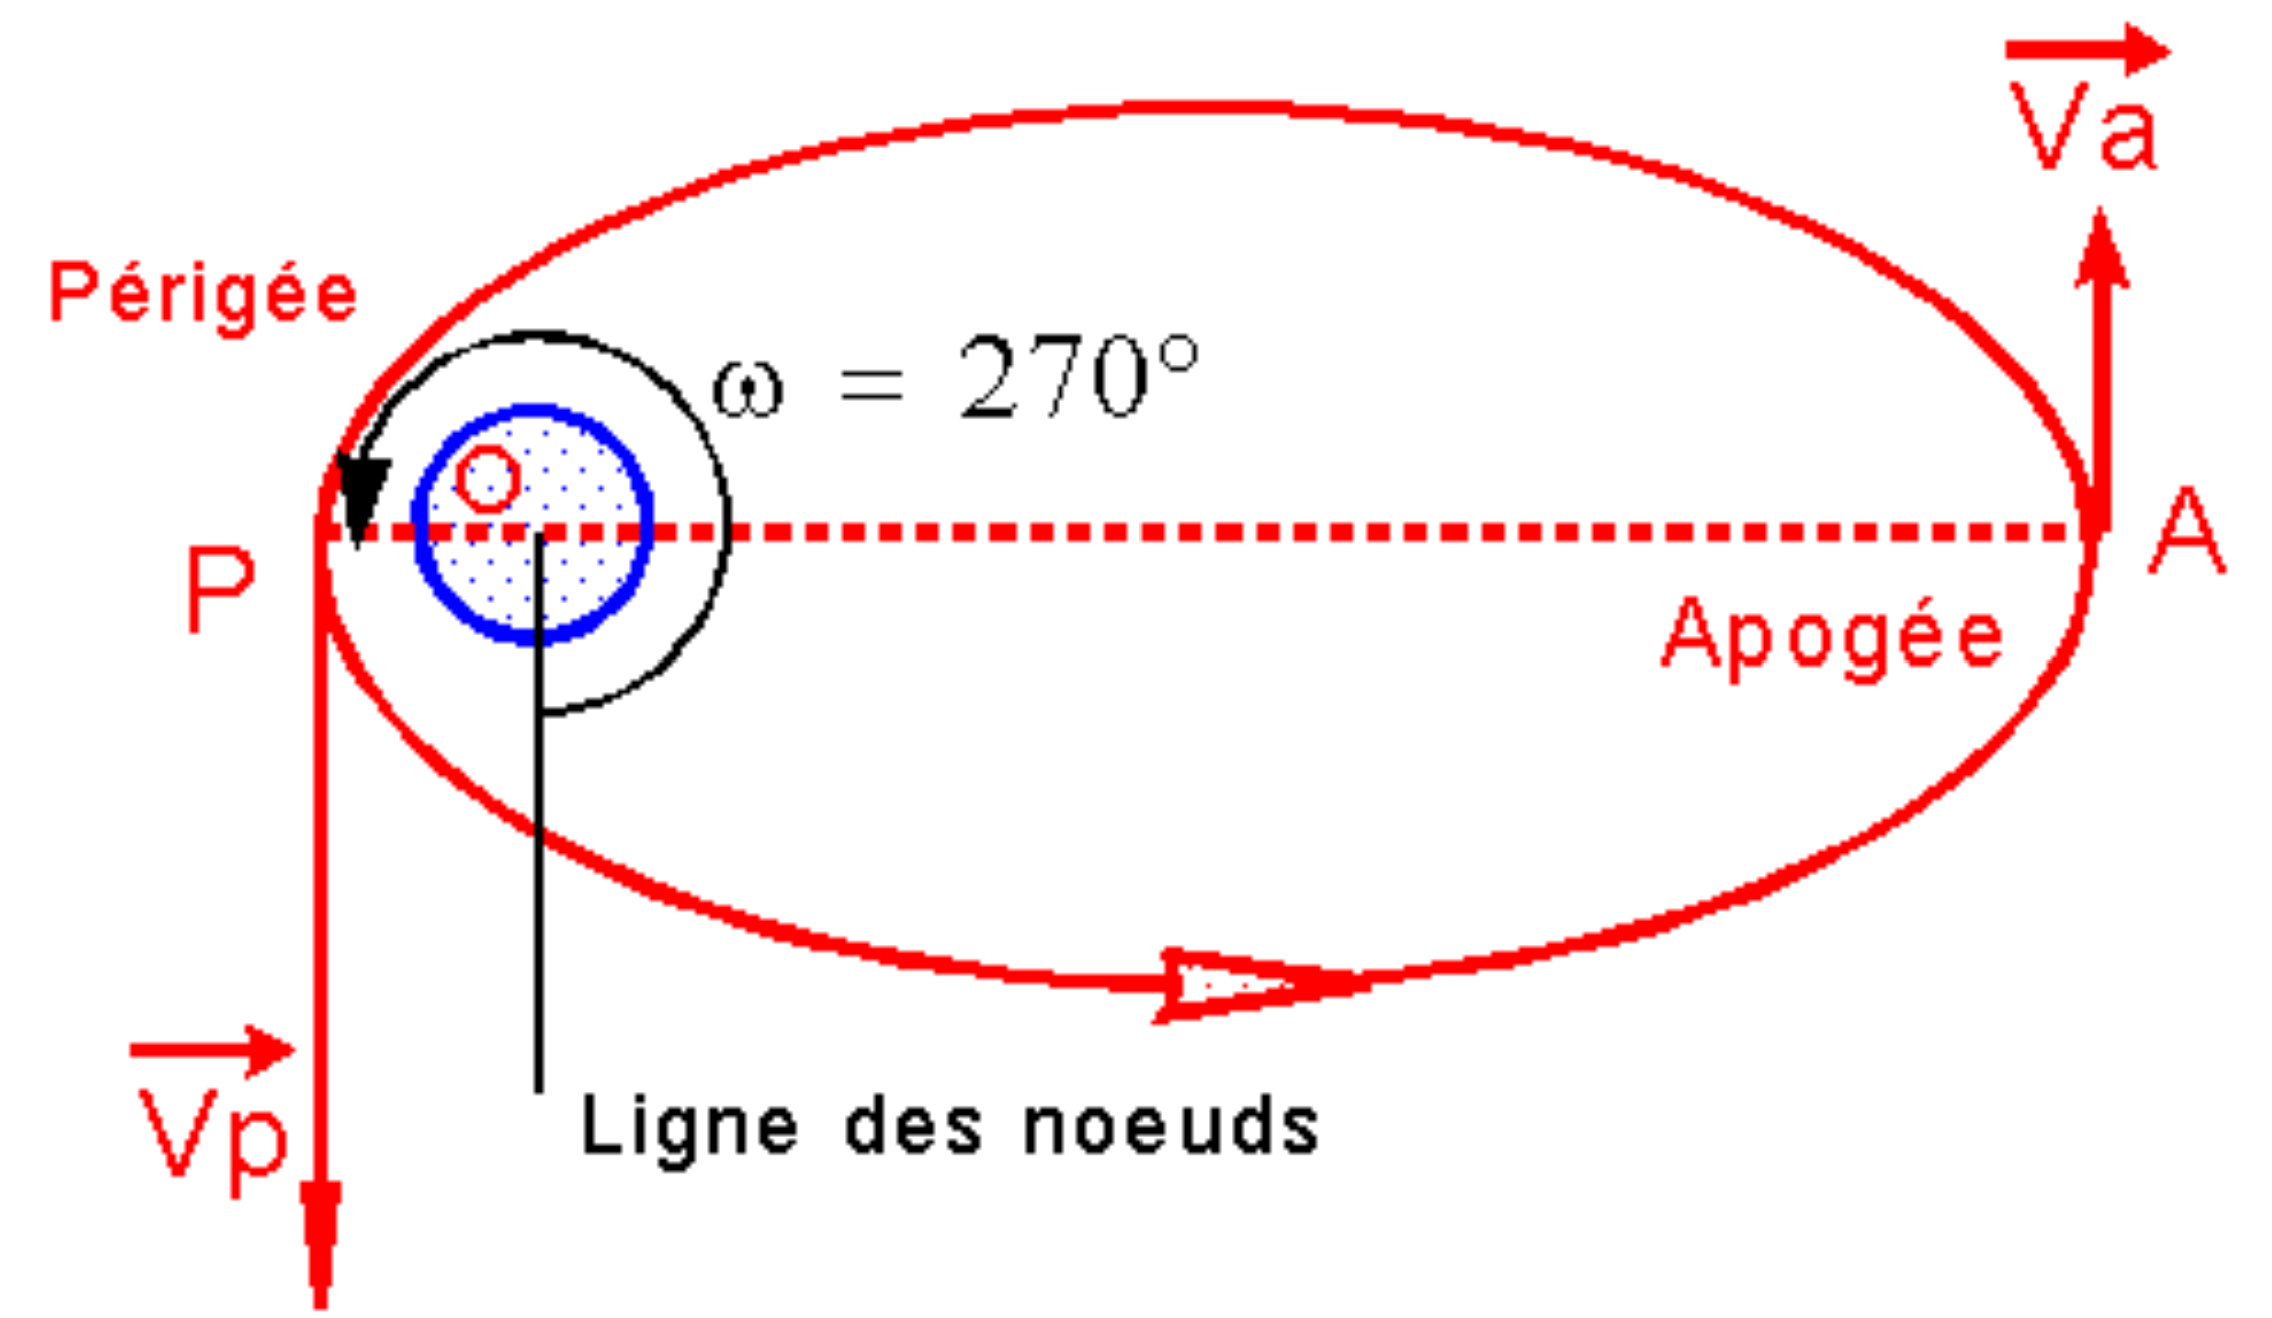

L'excentricité est donnée par : 

 
$$  e = \frac{r\_2 - r\_1}{r\_1\,\cos\nu\_1 - r\_2\,\cos\nu\_2}$$


La formule du demi grand axe est donnée par : 


$$a = \frac{r\_1}{1 + e\cos \nu\_1}\,(1 - e^2)$$


La période orbitale est donnée par : 


$$  T = 2\pi\sqrt{\frac{a^3}{\mu}}$$



%%Calcul de l'excentricité et du demi‑grand axe
r1 = R_T + h1;              % rayon à ν1
r2 = R_T + h2;              % rayon à ν2

% Résolution de l'équation r = a (1 - e^2)/(1 + e cos ν)
% On élimine a pour obtenir e
e = (r2 - r1) / (r1 * cos(nu1) - r2 * cos(nu2));
C = r1 * (1 + e * cos(nu1));
a = C / (1 - e^2);
p = a * (1 - e^2);

%% 1.1. Périgée et apogée
r_p = a * (1 - e);
r_a = a * (1 + e);
h_p = r_p - R_T;
h_a = r_a - R_T;

% Vitesses au périgée et à l'apogée
v_p = sqrt(mu * (2/r_p - 1/a));
v_a = sqrt(mu * (2/r_a - 1/a));

% Période orbitale
T_orbit = 2 * pi * sqrt(a^3 / mu);

fprintf('Excentricitée = %.6f\n', e);

Excentricitée = 0.143035


fprintf('Demi-grand axe a = %.3f km\n', a);

Demi-grand axe a = 8131.006 km


fprintf('Altitude au périgée = %.3f km\n', h_p);

Altitude au périgée = 589.851 km


fprintf('Altitude à l''apogée = %.3f km\n', h_a);

Altitude à l'apogée = 2915.881 km


fprintf('Vitesse au périgée = %.3f km/s\n', v_p);

Vitesse au périgée = 8.086 km/s


fprintf('Vitesse à l''apogée = %.3f km/s\n', v_a);

Vitesse à l'apogée = 6.063 km/s


fprintf('Période orbitale = %.3f min\n', T_orbit/60);

Période orbitale = 121.610 min


**Nœuds ascendant et descendant**

L'argument du périgée  est l'angle entre le nœud ascendant et le périgée dans le plan orbital.  L'anomalie vraie du nœud ascendant et celle du nœud descendant :


$$ $\nu\_{\text{AN}} = -\omega$ (modulo $2\pi$)$$



$$$\nu\_{\text{DN}} = \pi - \omega$$$


 En appliquant l'équation et la relation de vis‑viva, on obtient :


$$  \tan \frac{\nu}{2} = \sqrt{\frac{1+e}{1-e}}\,\tan \frac{E}{2},
$$



$$ $t = M/n$$$



$$$M = E - e \sin E$$n=\sqrt{\mu/a^3}$.$$



%% 2. Noeuds ascendant et descendant
nu_AN = -omega;
if nu_AN < 0
    nu_AN = nu_AN + 2*pi;
end
nu_DN = pi - omega;

r_AN = a * (1 - e^2) / (1 + e * cos(nu_AN));
r_DN = a * (1 - e^2) / (1 + e * cos(nu_DN));
h_AN = r_AN - R_T;
h_DN = r_DN - R_T;

v_AN = sqrt(mu * (2/r_AN - 1/a));
v_DN = sqrt(mu * (2/r_DN - 1/a));

n0 = sqrt(mu / a^3);

% Fonction pour calculer le temps depuis le périgée vers une anomalie nu
function t_local = tof_from_perigee(nu_val, ecc, nmean)
    tan_half_E = tan(nu_val/2) / sqrt((1+ecc)/(1-ecc));
    E = 2 * atan(tan_half_E);
    if E < 0
        E = E + 2*pi;
    end
    M_val = E - ecc * sin(E);
    t_local = M_val / nmean;
end

t_AN = tof_from_perigee(nu_AN, e, n0);
if t_AN < 0
    t_AN = t_AN + T_orbit;
end
t_DN = tof_from_perigee(nu_DN, e, n0);
if t_DN < 0
    t_DN = t_DN + T_orbit;
end

fprintf('  Anomalie vraie ν_AN = %.2f °\n', rad2deg(nu_AN));

  Anomalie vraie ν_AN = 355.00 °


fprintf('  Altitude = %.3f km\n', h_AN);

  Altitude = 593.171 km


fprintf('  Vitesse = %.3f km/s\n', v_AN);

  Vitesse = 8.083 km/s


fprintf('Temps depuis le périgée = %.3f min\n', t_AN/60);

Temps depuis le périgée = 120.357 min



fprintf('\nNœud descendant :\n');


Nœud descendant :


fprintf('  Anomalie vraie ν_DN     = %.2f °\n', rad2deg(nu_DN));

  Anomalie vraie ν_DN     = 175.00 °


fprintf('  Altitude = %.3f km\n', h_DN);

  Altitude = 2909.982 km


fprintf('  Vitesse = %.3f km/s\n', v_DN);

  Vitesse = 6.067 km/s


fprintf('  Temps depuis le périgée = %.3f min\n', t_DN/60);

  Temps depuis le périgée = 58.576 min


**Question 3  : Perturbations dominantes en orbite basse**

 La Terre est légèrement aplatie aux pôles.  Le développement harmonique du potentiel gravitationnel fait apparaître le terme J_2 qui provoque une régression du nœud ascendant et une rotation du périgée.

la haute atmosphère exerce une résistance qui diminue le demi‑grand axe et circularise l'orbite.  À l'altitude du périgée 590km, cette traînée est réduite mais non nulle.  D'autres perturbations (forces du Soleil et de la Lune, pression de radiation) existent mais sont moins importantes.

**Question 4-5-6-7  :  Évolutions séculaires dues au J_2**

Pour une orbite faiblement excentrique et inclinée, les dérivées séculaires moyennes des éléments orbitaux sous l'effet de J_2 sont :

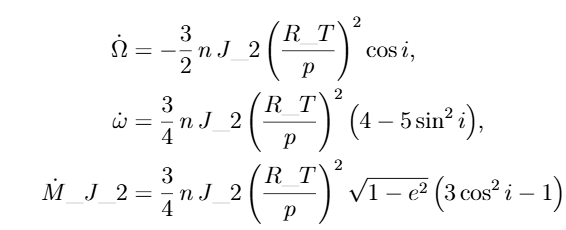

% Fonction locale calculant les dérives (en deg/jour)
function [dOmega_d, domega_d, dM_d] = j2_rates(a_val, e_val, i_rad, J2_val, R_val, mu_val)
    n_val = sqrt(mu_val / a_val^3);
    p_val = a_val * (1 - e_val^2);
    dOmega_dt  = -1.5 * n_val * J2_val * (R_val / p_val)^2 * cos(i_rad);
    domega_dt  = 0.75 * n_val * J2_val * (R_val / p_val)^2 * (5 * cos(i_rad)^2 - 1);
    dM_dt      = 0.75 * n_val * J2_val * (R_val / p_val)^2 * sqrt(1 - e_val^2) * (3 * cos(i_rad)^2 - 1);
    s_to_day   = 86400;
    rad_to_deg = 180/pi;
    dOmega_d = dOmega_dt * rad_to_deg * s_to_day;
    domega_d = domega_dt * rad_to_deg * s_to_day;
    dM_d     = dM_dt * rad_to_deg * s_to_day;
end

inclinations_deg = [64, 63.43494882, 116.56505118, 90];
results = zeros(numel(inclinations_deg),4);
for idx = 1:numel(inclinations_deg)
    inc_rad = deg2rad(inclinations_deg(idx));
    [dO, dw, dM] = j2_rates(a, e, inc_rad, J2, R_T, mu);
    results(idx,:) = [inclinations_deg(idx), dO, dw, dM];
end

fprintf(' Inclinaison   dΩ/dt        dω/dt        dM/dt_J2\n');

 Inclinaison   dΩ/dt        dω/dt        dM/dt_J2


for idx = 1:size(results,1)
    fprintf('  %8.3f   %10.4f   %10.4f   %10.4f\n', results(idx,1), results(idx,2), results(idx,3), results(idx,4));
end

    64.000      -1.9450      -0.0869      -0.9298
    63.435      -1.9842       0.0000      -0.8782
   116.565       1.9842       0.0000      -0.8782
    90.000      -0.0000      -2.2184      -2.1956


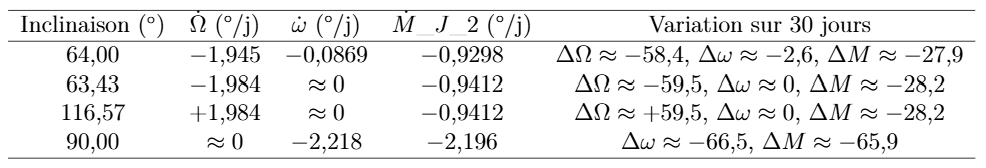

**Voir Comptre rendu pour la justification 4-5-6-7**

**Bonus : Tracer l'orbite en 2D et 3D**

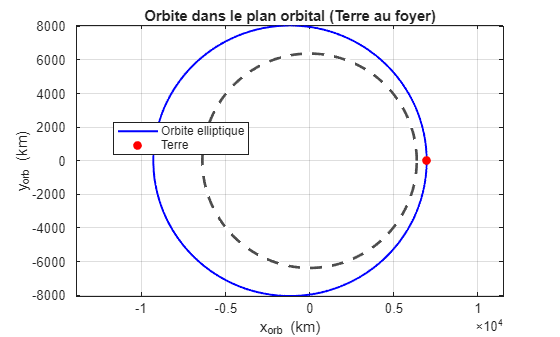


omega = deg2rad(5);    % argument du périgée
i     = deg2rad(64);   % inclinaison
Omega = 0;             % RAAN fixé à 0 pour le dessin (non donné dans l'énoncé)

N = 1000;
nu = linspace(0, 2*pi, N);
r  = a*(1 - e^2) ./ (1 + e*cos(nu));

x_orb = r .* cos(nu);  % axe P
y_orb = r .* sin(nu);  % axe Q

figure('Name','Orbite dans le plan orbital');
plot(x_orb, y_orb, 'b', 'LineWidth', 1.5); hold on;
viscircles([0 0], R_T, 'Color',[0.3 0.3 0.3],'LineStyle','--'); % Terre
plot(a*(1-e), 0, 'ro','MarkerFaceColor','r'); % périgée
axis equal; grid on;
xlabel('x_{orb} (km)');
ylabel('y_{orb} (km)');
title('Orbite dans le plan orbital (Terre au foyer)');
legend('Orbite elliptique','Terre','Périgée','Location','best');

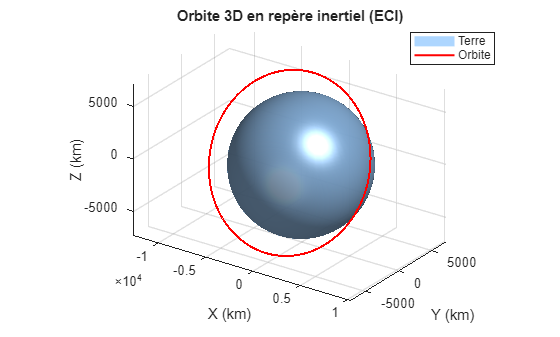

R3_Omega = [ cos(Omega) -sin(Omega) 0;
             sin(Omega)  cos(Omega) 0;
                     0           0  1 ];
R1_i = [ 1      0           0;
         0  cos(i)   -sin(i);
         0  sin(i)    cos(i) ];
R3_omega = [ cos(omega) -sin(omega) 0;
             sin(omega)  cos(omega) 0;
                      0           0 1 ];
Q_pqw_eci = R3_Omega * R1_i * R3_omega;   % matrice de rotation
r_pqw = [x_orb; y_orb; zeros(1,N)];
r_eci = Q_pqw_eci * r_pqw;
X = r_eci(1,:);
Y = r_eci(2,:);
Z = r_eci(3,:);

figure('Name','Orbite 3D autour de la Terre');
hold on; grid on; axis equal;
[xe, ye, ze] = sphere(60);
surf(R_T*xe, R_T*ye, R_T*ze, ...
     'FaceColor',[0.6 0.8 1], 'EdgeColor','none','FaceAlpha',0.8);
plot3(X, Y, Z, 'r', 'LineWidth', 1.5);
xlabel('X (km)');
ylabel('Y (km)');
zlabel('Z (km)');
title('Orbite 3D en repère inertiel (ECI)');
view(35,25);  
camlight; lighting phong;
legend('Terre','Orbite','Location','best');

# **Partie II :  Stratégies de Correction Orbitale et  Inclinaison puis Argument du Périgée **

On suppose que l’inclinaison doit être entre 62° et 65°.  L’orbite initiale possède une inclinaison i_0 = 64°. Afin de réduire naturellement les dérives séculaires dues à l’aplatissement terrestre, on souhaite placer le satellite sur une orbite à \textbf{inclinaison critique} prograde, pour laquelle la dérive de l’argument du périgée $\overset{\ldotp }{w}$ est nulle. 

%% Exercice 1 - Partie II : Correction d'inclinaison et effets J2
clear; clc;

%% Constantes Terre
R_T = 6378.14;       % km
mu  = 3.98610e5;     % km^3/s^2
J2  = 1.082e-3;      % -

g0     = 9.81;       % m/s^2
Isp    = 200;        % s
m0     = 3000;       % kg (masse initiale satellite)

%% Donnees orbitale (rappellees de la Partie I)
h1    = 2200;        % km
h2    = 800;         % km
nu1   = deg2rad(120);
nu2   = deg2rad(40);
omega = deg2rad(5);  % rad
i0    = deg2rad(64); % rad

% Calcul de a et e a partir des deux points (Partie I)
r1 = R_T + h1;
r2 = R_T + h2;

e = (r2 - r1) / (r1*cos(nu1) - r2*cos(nu2));
C = r1 * (1 + e*cos(nu1));
a = C / (1 - e^2);
p = a*(1 - e^2);
n = sqrt(mu/a^3);   % rad/s
T_orbit = 2*pi*sqrt(a^3/mu);  % s

fprintf('--- Rappel orbite ---\n');

--- Rappel orbite ---


fprintf('a = %.3f km, e = %.6f\n', a, e);

a = 8131.006 km, e = 0.143035


fprintf('T = %.3f min\n', T_orbit/60);

T = 121.610 min



%% Vitesse a l'apogee (manoeuvre de plan)
r_a = a*(1 + e);
v_a = sqrt(mu*(2/r_a - 1/a));    % km/s
v_a_ms = v_a*1000;               % m/s


**Question 8 :  Correction d'inclinaison**


i_crit1_deg = 63.43;             % inclinaison critique prograde
i_crit2_deg = 116.57;            % inclinaison critique retrograde
i_crit1 = deg2rad(i_crit1_deg);
i_crit2 = deg2rad(i_crit2_deg);

Delta_i = deg2rad(64 - i_crit1_deg);  % rad, variation d'i de 64 -> 63.43

% Delta V pour variation de plan a vitesse v_a
DeltaV = 2*v_a_ms*sin(Delta_i/2);     % m/s

% Masse d'ergols via Tsiolkovski
mr = exp( DeltaV / (Isp*g0) );        % m0/mf
mf = m0 / mr;                         % masse finale
m_prop = m0 - mf;                     % masse d'ergols consommee

fprintf('\n--- Q8 : Manoeuvre de correction d''inclinaison ---\n');


--- Q8 : Manoeuvre de correction d'inclinaison ---


fprintf('Inclinaison initiale i0  = 64.00 deg\n');

Inclinaison initiale i0  = 64.00 deg


fprintf('Inclinaison critique i1  = %.2f deg\n', i_crit1_deg);

Inclinaison critique i1  = 63.43 deg


fprintf('Delta i                  = %.4f deg\n', rad2deg(Delta_i));

Delta i                  = 0.5700 deg


fprintf('Vitesse a l''apogee v_a   = %.3f km/s\n', v_a);

Vitesse a l'apogee v_a   = 6.063 km/s


fprintf('DeltaV plan change       = %.2f m/s\n', DeltaV);

DeltaV plan change       = 60.31 m/s


fprintf('Masse initiale m0        = %.1f kg\n', m0);

Masse initiale m0        = 3000.0 kg


fprintf('Masse finale mf          = %.1f kg\n', mf);

Masse finale mf          = 2909.2 kg


fprintf('Masse d''ergols consommee = %.1f kg\n', m_prop);

Masse d'ergols consommee = 90.8 kg


fprintf('Instant de la manoeuvre (depuis perigee) ~ T/2 = %.2f min\n', (T_orbit/2)/60);

Instant de la manoeuvre (depuis perigee) ~ T/2 = 60.81 min


**Question 9 : Derives seculaires apres correction (J2)**

days = 30;

[Om_dot_64, w_dot_64, Mj2_dot_64] = j2_rates_deg_per_day(a,e,deg2rad(64),J2,R_T,mu);
[Om_dot_crit1, w_dot_crit1, Mj2_dot_crit1] = j2_rates_deg_per_day(a,e,i_crit1,J2,R_T,mu);
[Om_dot_crit2, w_dot_crit2, Mj2_dot_crit2] = j2_rates_deg_per_day(a,e,i_crit2,J2,R_T,mu);

fprintf('\n--- Q9 : Derives seculaires sur 30 jours ---\n');


--- Q9 : Derives seculaires sur 30 jours ---


fprintf('Avant correction (i = 64 deg):\n');

Avant correction (i = 64 deg):


fprintf('  dOmega/dt = %.4f deg/j, domega/dt = %.4f deg/j, dM_J2/dt = %.4f deg/j\n', ...
        Om_dot_64, w_dot_64, Mj2_dot_64);

  dOmega/dt = -1.9450 deg/j, domega/dt = -0.0869 deg/j, dM_J2/dt = -0.9298 deg/j


fprintf('  DeltaOmega_30j = %.3f deg, Deltaomega_30j = %.3f deg, DeltaM_30j = %.3f deg\n', ...
        Om_dot_64*days, w_dot_64*days, Mj2_dot_64*days);

  DeltaOmega_30j = -58.349 deg, Deltaomega_30j = -2.606 deg, DeltaM_30j = -27.894 deg



fprintf('\nApres correction (i1 = %.2f deg):\n', i_crit1_deg);


Apres correction (i1 = 63.43 deg):


fprintf('  dOmega/dt = %.4f deg/j, domega/dt = %.4f deg/j, dM_J2/dt = %.4f deg/j\n', ...
        Om_dot_crit1, w_dot_crit1, Mj2_dot_crit1);

  dOmega/dt = -1.9845 deg/j, domega/dt = 0.0008 deg/j, dM_J2/dt = -0.8778 deg/j


fprintf('  DeltaOmega_30j = %.3f deg, Deltaomega_30j = %.3f deg, DeltaM_30j = %.3f deg\n', ...
        Om_dot_crit1*days, w_dot_crit1*days, Mj2_dot_crit1*days);

  DeltaOmega_30j = -59.536 deg, Deltaomega_30j = 0.023 deg, DeltaM_30j = -26.333 deg



fprintf('\nInclinaison critique retrograde (i2 = %.2f deg):\n', i_crit2_deg);


Inclinaison critique retrograde (i2 = 116.57 deg):


fprintf('  dOmega/dt = %.4f deg/j, domega/dt = %.4f deg/j, dM_J2/dt = %.4f deg/j\n', ...
        Om_dot_crit2, w_dot_crit2, Mj2_dot_crit2);

  dOmega/dt = 1.9845 deg/j, domega/dt = 0.0008 deg/j, dM_J2/dt = -0.8778 deg/j


fprintf('  DeltaOmega_30j = %.3f deg, Deltaomega_30j = %.3f deg, DeltaM_30j = %.3f deg\n', ...
        Om_dot_crit2*days, w_dot_crit2*days, Mj2_dot_crit2*days);

  DeltaOmega_30j = 59.536 deg, Deltaomega_30j = 0.023 deg, DeltaM_30j = -26.333 deg



%% ==== Fonction locale pour les derives J2 (deg/j) ====
function [dOmega_d, domega_d, dM_J2_d] = j2_rates_deg_per_day(a, e, i, J2, R_T, mu)
    % Derives seculaires dues a J2 en deg/jour
    n = sqrt(mu/a^3);
    p = a*(1 - e^2);
    fac = J2*(R_T/p)^2;
    dOmega_dt  = -1.5 * n * fac * cos(i);
    domega_dt  =  0.75 * n * fac * (5*cos(i)^2 - 1);
    dM_J2_dt   =  0.75 * n * fac * sqrt(1-e^2) * (3*cos(i)^2 - 1);  % partie J2 seulement
    s2day      = 86400;
    rad2deg    = 180/pi;
    dOmega_d   = dOmega_dt * s2day * rad2deg;
    domega_d   = domega_dt * s2day * rad2deg;
    dM_J2_d    = dM_J2_dt * s2day * rad2deg;
end


**Question 10 et 11 : Correction de l’argument du périgée Dérives séculaires dues au J2 après correction de w : **

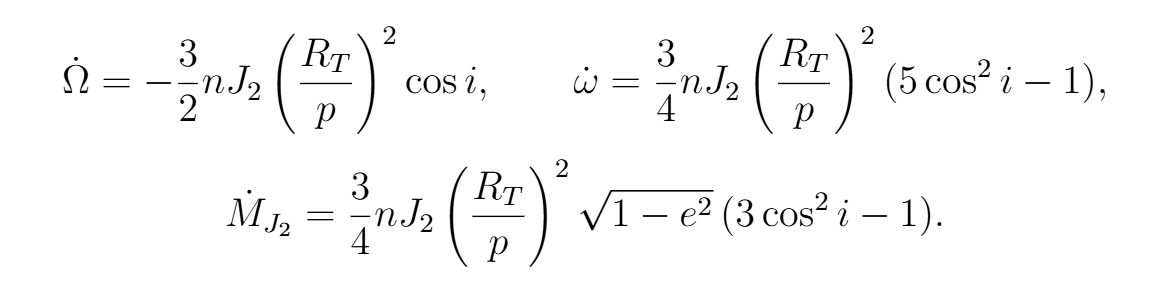


%% Donnees orbitale (apres correction d'inclinaison)
% On reprend a, e, i_critique ~= 63.43 deg
a = 8131;             % km (valeur approx de la Partie I)
e = 0.143;            % -
i = deg2rad(63.43);   % rad

% Vitesses aux apsides (a ajuster avec tes valeurs precises)
r_p = a*(1 - e);
r_a = a*(1 + e);
v_p = sqrt(mu*(2/r_p - 1/a));   % km/s
v_a = sqrt(mu*(2/r_a - 1/a));   % km/s

v_p_ms = v_p*1000;
v_a_ms = v_a*1000;

%% 1) Trajectoire 3D avant et après correction inclinaison
nu = linspace(0,2*pi,600);
r  = a*(1-e^2)./(1+e*cos(nu));
x_orb = r.*cos(nu);
y_orb = r.*sin(nu);

%% Correction de l'argument du perigee : Delta omega = -5 deg
Delta_omega_deg = -5;
Delta_omega = deg2rad(Delta_omega_deg);     % rad
delta = Delta_omega/4;                      % pour la formule approx


DeltaV_p = abs(2*v_p_ms*sin(delta));% m/s
DeltaV_a = abs(2*v_a_ms*sin(delta));% m/s
DeltaV_tot = DeltaV_p + DeltaV_a;


DeltaV_tot = DeltaV_p + DeltaV_a;

fprintf('v_p = %.3f km/s, v_a = %.3f km/s\n', v_p, v_a);

v_p = 8.086 km/s, v_a = 6.063 km/s


fprintf('DeltaV_p ~ %.1f m/s, DeltaV_a ~ %.1f m/s, DeltaV_tot ~ %.1f m/s\n', ...
        DeltaV_p, DeltaV_a, DeltaV_tot);

DeltaV_p ~ 352.8 m/s, DeltaV_a ~ 264.5 m/s, DeltaV_tot ~ 617.3 m/s


% Masse d'ergols, en partant de ~2910 kg apres la correction d'inclinaison
i0 = deg2rad(64);   % avant correction
i1 = deg2rad(63.43);% apres correction (inclinaison critique)
m0 = 2910;                        % kg
mr = exp(DeltaV_tot/(Isp*g0));    % m0 / mf
mf = m0/mr;
m_prop = m0 - mf;
omega0 = deg2rad(5);% avant correction
omega1 = deg2rad(0);% apres correction Q10

fprintf('Masse initiale m0  = %.1f kg\n', m0);

Masse initiale m0  = 2910.0 kg


fprintf('Masse finale mf    = %.1f kg\n', mf);

Masse finale mf    = 2124.5 kg


fprintf('Masse d''ergols     = %.1f kg\n', m_prop);

Masse d'ergols     = 785.5 kg


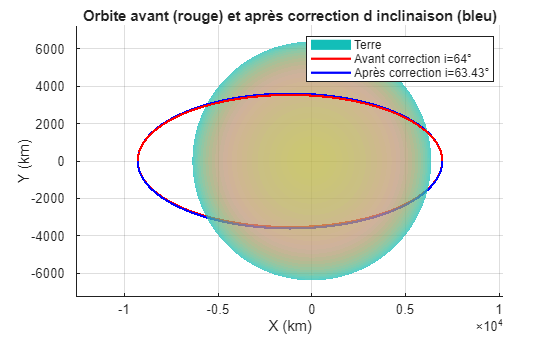

% Conversion PQW -> ECI pour i0 et i1
R3 = @(Omega)[cos(Omega) -sin(Omega) 0; sin(Omega) cos(Omega) 0; 0 0 1];
R1 = @(a)[1 0 0; 0 cos(a) -sin(a); 0 sin(a) cos(a)];

Q0 = R3(0)*R1(i0);      % repère avant correction inclinaison
Q1 = R3(0)*R1(i1);      % repère après correction inclinaison

r3D_0 = Q0*[x_orb; y_orb; 0*x_orb];
r3D_1 = Q1*[x_orb; y_orb; 0*x_orb];

figure('Name','Comparaison 3D – Correction inclinaison');
hold on; grid on; axis equal;
% Terre
[xs,ys,zs]=sphere(60); surf(R_T*xs,R_T*ys,R_T*zs,'FaceAlpha',0.5,'EdgeColor','none');
% Orbites
plot3(r3D_0(1,:),r3D_0(2,:),r3D_0(3,:),'r','LineWidth',1.6)
plot3(r3D_1(1,:),r3D_1(2,:),r3D_1(3,:),'b','LineWidth',1.6)
title('Orbite avant (rouge) et après correction d inclinaison (bleu)');
xlabel('X (km)'); ylabel('Y (km)'); zlabel('Z (km)');
legend('Terre','Avant correction i=64°','Après correction i=63.43°');

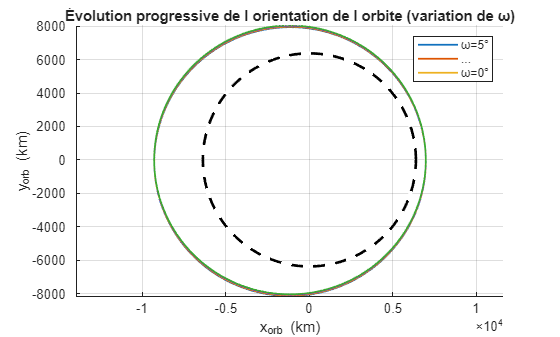


%% 2) Correction argument périgée : rotation dans PQW
omega_vec = linspace(omega0,omega1,5);
figure('Name','Rotation de ω dans le plan orbital');
hold on; grid on; axis equal;

for k = 1:length(omega_vec)
    om = omega_vec(k);
    Qp = [ cos(om) -sin(om) 0;
           sin(om)  cos(om) 0;
                0       0   1 ];
    rr = Qp*[x_orb; y_orb; 0*x_orb];
    plot(rr(1,:),rr(2,:),'LineWidth',1.3)
end
viscircles([0 0], R_T,'Color','k','LineStyle','--');
title('Évolution progressive de l orientation de l orbite (variation de ω)');
xlabel('x_{orb} (km)'); ylabel('y_{orb} (km)');
legend('ω=5°','...','ω=0°');

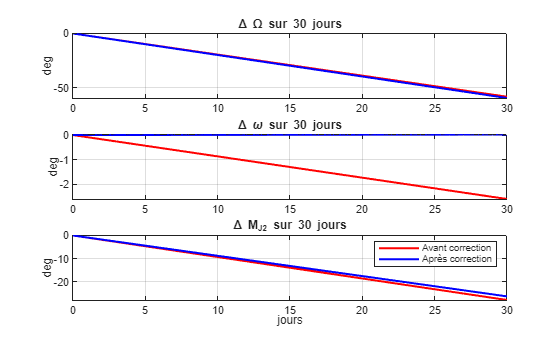


%% Évolution des dérives séculaires sur 30 jours
days = 0:30;

% Fonctions dérives J2
j2_dOmega = @(i) -1.5*sqrt(mu/a^3)*J2*(R_T/(a*(1-e^2)))^2*cos(i)*(86400*180/pi);
j2_domega = @(i)  0.75*sqrt(mu/a^3)*J2*(R_T/(a*(1-e^2)))^2*(5*cos(i)^2-1)*(86400*180/pi);
j2_dM     = @(i)  0.75*sqrt(mu/a^3)*J2*(R_T/(a*(1-e^2)))^2*sqrt(1-e^2)*(3*cos(i)^2-1)*(86400*180/pi);

% Avant correction inclinaison
Om_64 = j2_dOmega(i0)*days;
om_64 = j2_domega(i0)*days;
M_64  = j2_dM(i0)*days;

% Après correction inclinaison i=63.43°
Om_63 = j2_dOmega(i1)*days;
om_63 = j2_domega(i1)*days;
M_63  = j2_dM(i1)*days;

figure('Name','Dérives J2 – Avant/Après correction inclinaison');
subplot(3,1,1)
plot(days,Om_64,'r','LineWidth',1.5); hold on;
plot(days,Om_63,'b','LineWidth',1.5);
title('\Delta \Omega sur 30 jours'); ylabel('deg'); grid on;

subplot(3,1,2)
plot(days,om_64,'r','LineWidth',1.5); hold on;
plot(days,om_63,'b','LineWidth',1.5);
title('\Delta \omega sur 30 jours'); ylabel('deg'); grid on;

subplot(3,1,3)
plot(days,M_64,'r','LineWidth',1.5); hold on;
plot(days,M_63,'b','LineWidth',1.5);
title('\Delta M_{J2} sur 30 jours'); ylabel('deg'); xlabel('jours'); grid on;
legend('Avant correction','Après correction');

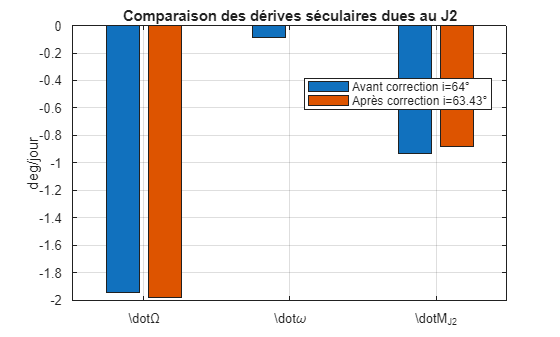

%%Résumé barres comparatives
figure('Name','Dérives séculaires J2 – Comparaison');
bar([ j2_dOmega(i0), j2_dOmega(i1); ...
      j2_domega(i0), j2_domega(i1); ...
      j2_dM(i0),     j2_dM(i1) ]);
set(gca,'XTickLabel',{'\dot{\Omega}','\dot{\omega}','\dot{M}_{J2}'})
ylabel('deg/jour')
legend('Avant correction i=64°','Après correction i=63.43°','Location','best')
title('Comparaison des dérives séculaires dues au J2')
grid on;

# **Partie III : Influence de l’Ordre des Manœuvres : Correction de ω puis de l’Inclinaison**

**Question 12 et 13 : **

On reprend les mêmes paramètres orbitaux que dans les parties précédentes. On souhaite, dans un premier temps, corriger l’orientation de l’orbite et obtenir un argument du périgée nul (w_f = 0°), avant de mettre l’orbite à l’inclinaison critique i_1 = 63.43° On utilise : 

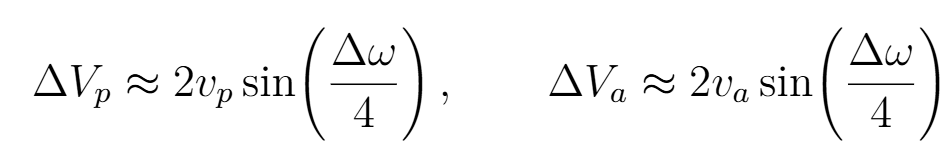


%% Exercice 1 - Partie III : on corrige d'abord omega, puis l'inclinaison
clear; clc;

%% Constantes
R_T = 6378.14;          % km
mu  = 3.98610e5;        % km^3/s^2
J2  = 1.082e-3;         % -
g0  = 9.81;             % m/s^2
Isp = 200;              % s

%% Orbite (rappel Partie I)
h1    = 2200;           % km @ nu1 = 120°
h2    = 800;            % km @ nu2 = 40°
nu1   = deg2rad(120);
nu2   = deg2rad(40);
i0    = deg2rad(64);    % inclinaison initiale
omega0_deg = 5;         % deg

r1 = R_T + h1;
r2 = R_T + h2;

e = (r2 - r1) / (r1*cos(nu1) - r2*cos(nu2));
C = r1 * (1 + e*cos(nu1));
a = C / (1 - e^2);
p = a*(1 - e^2);

n     = sqrt(mu/a^3);   % rad/s
T_orb = 2*pi*sqrt(a^3/mu);

%% Vitesses perigee / apogee
r_p = a*(1 - e);
r_a = a*(1 + e);
v_p = sqrt(mu*(2/r_p - 1/a));    % km/s
v_a = sqrt(mu*(2/r_a - 1/a));    % km/s
v_p_ms = v_p*1000;
v_a_ms = v_a*1000;

%% --- Q12 : 1) Correction de l'argument du perigee d'abord ---
m0 = 3000;             % kg masse initiale

Delta_omega_deg = 5;   % on corrige 5° -> 0°
delta = deg2rad(Delta_omega_deg/4);   % petit angle pour formule approx

DeltaV_p = abs(2*v_p_ms*sin(delta));  % m/s
DeltaV_a = abs(2*v_a_ms*sin(delta));  % m/s
DeltaV_omega = DeltaV_p + DeltaV_a;

fprintf('v_p = %.3f km/s, v_a = %.3f km/s\n', v_p, v_a);


--- Partie III : correction de omega en premier ---


v_p = 8.086 km/s, v_a = 6.063 km/s


fprintf('DeltaV_p(omega) = %.2f m/s\n', DeltaV_p);

DeltaV_p(omega) = 352.80 m/s


fprintf('DeltaV_a(omega) = %.2f m/s\n', DeltaV_a);

DeltaV_a(omega) = 264.51 m/s


fprintf('DeltaV_omega_tot = %.2f m/s\n', DeltaV_omega);

DeltaV_omega_tot = 617.31 m/s



% Masse apres correction de omega
mr_omega = exp( DeltaV_omega / (Isp*g0) );  % m0/m1
m1 = m0 / mr_omega;
m_prop_omega = m0 - m1;

fprintf('Masse apres correction de omega : m1 = %.1f kg\n', m1);

Masse apres correction de omega : m1 = 2190.2 kg


fprintf('Ergols consommés pour omega     : %.1f kg\n', m_prop_omega);

Ergols consommés pour omega     : 809.8 kg



i_crit1_deg = 63.43;         % inclinaison critique prograde
Delta_i_deg = 64 - i_crit1_deg;
Delta_i = deg2rad(Delta_i_deg);

DeltaV_i = 2*v_a_ms*sin(Delta_i/2);   % m/s (variation de plan a l'apogee)

mr_i = exp( DeltaV_i / (Isp*g0) );
m2 = m1 / mr_i;
m_prop_i = m1 - m2;

fprintf('Delta i = %.4f deg -> DeltaV_i = %.2f m/s\n', Delta_i_deg, DeltaV_i);

Delta i = 0.5700 deg -> DeltaV_i = 60.31 m/s


fprintf('Masse finale m2 = %.1f kg\n', m2);

Masse finale m2 = 2123.9 kg


fprintf('Ergols consommés pour i = %.1f kg\n', m_prop_i);

Ergols consommés pour i = 66.3 kg



%% Bilan Partie III
m_prop_total_III = m_prop_omega + m_prop_i;
fprintf('Ergols totaux (omega puis i) : %.1f kg\n', m_prop_total_III);

Ergols totaux (omega puis i) : 876.1 kg



%% Comparaison avec Partie II (inclinaison puis omega)
% On recalcule les memes DeltaV mais dans l'autre ordre
DeltaV_i_II     = DeltaV_i;
DeltaV_omega_II = DeltaV_omega;

mr_i_II     = exp( DeltaV_i_II / (Isp*g0) );
m1_II       = m0 / mr_i_II;
m_prop_i_II = m0 - m1_II;

mr_omega_II     = exp( DeltaV_omega_II / (Isp*g0) );
m2_II           = m1_II / mr_omega_II;
m_prop_omega_II = m1_II - m2_II;

m_prop_total_II = m_prop_i_II + m_prop_omega_II;

fprintf('Ergols totaux (i puis omega) : %.1f kg\n', m_prop_total_II);

Ergols totaux (i puis omega) : 876.1 kg


fprintf('Difference (III - II)       : %.3f kg (doit être ~0, différences = arrondis)\n', ...
        m_prop_total_III - m_prop_total_II);

Difference (III - II)       : 0.000 kg (doit être ~0, différences = arrondis)
